# Reconeixament

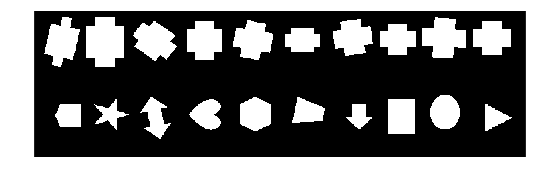

BW = rgb2gray(imread("creus_no_creus.png")) < 200;
imshow(BW);


BWU = BW(1:end/2,:);
BWD = BW(end/2:end,:);

CCU = bwconncomp(BWU);
CCD = bwconncomp(BWD);

NumObj = CCU.NumObjects;

propsU = regionprops('table',CCU,'Centroid','BoundingBox','Perimeter','Circularity','Solidity','Extent','MinorAxisLength','MajorAxisLength','MaxFeretProperties','MinFeretProperties');
propsD = regionprops('table',CCD,'Centroid','BoundingBox','Perimeter','Circularity','Solidity','Extent','MinorAxisLength','MajorAxisLength','MaxFeretProperties','MinFeretProperties');

FU = [propsU.Perimeter./propsU.MinFeretDiameter, propsU.Circularity,propsU.Solidity propsU.Extent, propsU.MinorAxisLength./propsU.MajorAxisLength, propsU.MinFeretDiameter./propsU.MaxFeretDiameter];
FD = [propsD.Perimeter./propsD.MinFeretDiameter, propsD.Circularity,propsD.Solidity propsD.Extent, propsD.MinorAxisLength./propsD.MajorAxisLength, propsD.MinFeretDiameter./propsD.MaxFeretDiameter];

Features = [FU;FD];
Output = false([2*NumObj,1]);
Output(1:NumObj) = true;

classificador1.predictFcn(Features);